%% =========================================================================
% UNIFICADO: IDENTIFICACIÓN EXPERIMENTAL + DISEÑO CONTROLADOR PI
% Versión Final: Ajustado a ts <= 1.0 s y Corregido para ess = 0
% =========================================================================

clear; clc; close all;

%% 1) CONFIGURACIÓN DE IDENTIFICACIÓN Y DISEÑO
nombreArchivo   = 'datos_barrido_Com_P.csv'; 
PWM_MIN         = 125;   
PWM_IGNORE_FROM = 115;
PWM_IGNORE_TO   = 125;
T_step          = 5.0;
T_pre_win       = 0.5;
T_post_win      = 5.0;
T_regime_width  = 1.0;

% --- ESPECIFICACIONES DE DISEÑO AJUSTADAS (t_s PRACTICO) ---
ts_deseado = 1.0;   % Tiempo de asentamiento (s)
Mp_deseado = 0.05;  % Sobreimpulso (5% -> 0.05)


%% 2) CARGAR DATOS
try
    data   = readtable(nombreArchivo);
    t_ms   = data.t_ms;
    u_pwm  = data.PWM;
    p_kPa  = data.Presion_kPa;
    t_s    = t_ms / 1000.0;
    Ts_prom = mean(diff(t_s));
    fprintf('Datos cargados. Ts promedio ≈ %.4f s\n', Ts_prom);
catch
    error('ERROR: No se pudo cargar el archivo "%s". Asegúrese de que exista.', nombreArchivo);
end

Datos cargados. Ts promedio ≈ 0.0100 s




%% 3) SEGMENTACIÓN Y CÁLCULO DE K Y TAU POR ESCALÓN (Identificación)
% --- Lógica de su script de identificación para obtener K_list y tau_list ---
idxCambios = find(diff(u_pwm) ~= 0);
idxInicio  = [1; idxCambios + 1];
idxFin     = [idxCambios; length(u_pwm)];
nTramos    = numel(idxInicio);

pwm0_list  = []; pwm1_list  = []; K_list     = []; tau_list   = []; tstep_list = []; y0_list = []; yinf_list = [];

for k = 1:nTramos-1
    i1 = idxInicio(k); i2 = idxFin(k); j1 = idxInicio(k+1); j2 = idxFin(k+1);
    pwm_before = u_pwm(i1); pwm_after  = u_pwm(j1);

    if pwm_after <= pwm_before || pwm_after < PWM_MIN || ...
       (pwm_before == PWM_IGNORE_FROM && pwm_after == PWM_IGNORE_TO) || ...
       (t_s(j2) - t_s(j1)) < (T_step - Ts_prom)
        continue;
    end
    
    t_step = t_s(j1);
    t_ini_win = t_step - T_pre_win;
    t_fin_win = t_step + T_post_win;
    idx_window = find( t_s >= t_ini_win & t_s <= t_fin_win );
    if numel(idx_window) < 10; continue; end
    
    t_win = t_s(idx_window);
    p_win = p_kPa(idx_window);

    idx_before = find(t_win < t_step); idx_after  = find(t_win >= t_step);

    if isempty(idx_before) || numel(idx_after) < 5; continue; end

    p_before = p_win(idx_before); p_after  = p_win(idx_after);
    
    t_ini_y0 = t_step - T_pre_win;
    idx_y0   = find( t_win(idx_before) >= t_ini_y0 );
    y0 = mean( p_before(idx_y0) );

    t_ini_reg = t_step + (T_post_win - T_regime_width);
    idx_regime = find( t_win(idx_after) >= t_ini_reg );
    if isempty(idx_regime)
        idx_regime = max(1, numel(p_after)-5) : numel(p_after);
    end
    y_inf = mean( p_after(idx_regime) );

    du = pwm_after - pwm_before;
    dy = y_inf - y0;
    K_val  = dy / du;
    
    frac = 1 - exp(-1);
    y_target = y0 + frac * dy;
    
    idxTau = [];
    if dy > 0
        idxTau = find(p_after >= y_target, 1, 'first');
    elseif dy < 0
        idxTau = find(p_after <= y_target, 1, 'first');
    end

    if isempty(idxTau)
        tau_val = NaN;
    else
        t_tau_abs = t_win(idx_after(idxTau));
        tau_val = t_tau_abs - t_step;
    end

    pwm0_list  = [pwm0_list; pwm_before]; pwm1_list  = [pwm1_list; pwm_after];
    K_list     = [K_list;    K_val]; tau_list   = [tau_list;  tau_val];
    tstep_list = [tstep_list; t_step]; y0_list = [y0_list; y0]; yinf_list = [yinf_list; y_inf];
end


%% 4. CÁLCULO DEL MODELO LTI REPRESENTATIVO (Paso 1 del Reporte)
idx_design_region = find(pwm1_list >= 125 & pwm1_list <= 180);

K_design = mean(K_list(idx_design_region));
tau_design = mean(tau_list(idx_design_region));

fprintf('\n--- MODELO DE DISEÑO (PROMEDIO en PWM 125-180) ---\n');


--- MODELO DE DISEÑO (PROMEDIO en PWM 125-180) ---


fprintf('Ganancia K_design: %.4f kPa/PWM \n', K_design);

Ganancia K_design: 0.0649 kPa/PWM 


fprintf('Tau_design: %.4f s \n', tau_design);

Tau_design: 0.0750 s 



s = tf('s');
G = K_design / (tau_design*s + 1);
disp('G(s) para Diseño:');

G(s) para Diseño:


disp(G);

  tf with properties:

       Numerator: {[0 0.0649]}
     Denominator: {[0.0750 1]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]





%% 5. DISEÑO DEL CONTROLADOR PI (Pasos 3 y 4 - Root Locus AJUSTADO)

% --- A. Cálculo de Polos Deseados s_d (Capítulo 3.4) ---
Mp_factor = Mp_deseado;
zeta = sqrt(log(Mp_factor)^2 / (pi^2 + log(Mp_factor)^2));
sigma = 4.6 / ts_deseado; % Nuevo sigma para ts <= 1.0 s
omega_d = sigma * sqrt(1 - zeta^2) / zeta;
sd = -sigma + 1i*omega_d;

% --- B. Cálculo del Cero 'z' (Condición de Ángulo - Capítulo 5.3) ---
angle_p_pi = angle(sd - 0); 
angle_p_g = angle(sd - (-1/tau_design)); 
angle_z_req = angle_p_pi + angle_p_g - pi; 

z = sigma - (omega_d / tan(angle_z_req));

% --- C. Cálculo de la Ganancia Kp (Condición de Magnitud - Capítulo 5.4) ---
Kp_val = abs(sd) * abs(sd + 1/tau_design) / (abs(sd + z) * (K_design/tau_design));
Ki_val = Kp_val * z;

% --- D. Definición Explícita del Controlador (CORRECCIÓN DE ess) ---
num_d = Kp_val * [1, z];
den_d = [1, 0]; % Asegura el polo en s=0 (Sistema Tipo 1)
D_PI_explicit = tf(num_d, den_d);

L_open_check = D_PI_explicit * G;
T_closed_check = feedback(L_open_check, 1);

fprintf('\n--- CONTROLADOR PI RESULTANTE (AJUSTADO) ---\n');


--- CONTROLADOR PI RESULTANTE (AJUSTADO) ---


fprintf('Kp: %.4f, Ki: %.4f (z = %.4f)\n', Kp_val, Ki_val, z);

Kp: 4.7779, Ki: 95.3154 (z = 19.9494)


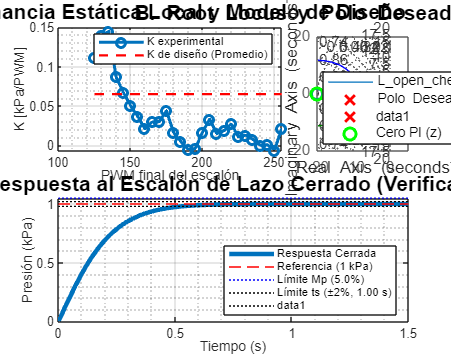

% 

%% 6. VISUALIZACIÓN EDUCATIVA Y VERIFICACIÓN (Paso 5)

LW = 2.0; FS = 12;
figure('Name', 'Analisis Completo: Identificacion + Diseno PI', 'Color', 'w', 'Position', [100, 100, 1000, 800]);

% --- SUBPLOT 1: No Linealidad (K vs PWM) ---
subplot(2, 3, [1 2]);
plot(pwm1_list, K_list, '-o', 'LineWidth', LW);
hold on;
plot([pwm1_list(1) pwm1_list(end)], [K_design K_design], '--r', 'LineWidth', 1.5);
grid on; grid minor;
xlabel('PWM final del escalón'); ylabel('K [kPa/PWM]');
title('A. Ganancia Estática Local y Modelo de Diseño', 'FontSize', FS+2);
legend('K experimental', 'K de diseño (Promedio)', 'Location', 'northeast');

% --- SUBPLOT 2: Root Locus y Diseño ---
subplot(2, 3, 3);
rlocus(L_open_check);
hold on;
plot(real(sd), imag(sd), 'rx', 'MarkerSize', 10, 'LineWidth', LW, 'DisplayName', 'Polo Deseado (s_d)');
plot(real(sd), -imag(sd), 'rx', 'MarkerSize', 10, 'LineWidth', LW);
plot(-z, 0, 'go', 'MarkerSize', 8, 'LineWidth', LW, 'DisplayName', 'Cero PI (z)');

title('B. Root Locus y Polo Deseado s_d (Capítulo 5)', 'FontSize', FS+2);
axis([-20 5 -20 20]);
legend('show', 'Location', 'southwest');
grid on;
% 

% --- SUBPLOT 3, 4, 5: Respuesta al Escalón y Verificación ---
subplot(2, 3, [4 5 6]);
[y, t] = step(T_closed_check, 1.5); % Simular
plot(t, y, 'LineWidth', 3, 'DisplayName', 'Respuesta Cerrada');
hold on;
plot(t, ones(size(t)), '--r', 'DisplayName', 'Referencia (1 kPa)');
plot(t, 1 + Mp_deseado*ones(size(t)), ':b', 'DisplayName', sprintf('Límite Mp (%.1f%%)', Mp_deseado*100));
plot(t, 1.02*ones(size(t)), ':k', 'DisplayName', sprintf('Límite ts (±2%%, %.2f s)', ts_deseado));
plot(t, 0.98*ones(size(t)), ':k');

% --- CÁLCULO Y LÓGICA CONDICIONAL ---
info = stepinfo(y, t);
ts_real = info.SettlingTime;
Mp_real = info.Overshoot;
ess_real = 1 - y(end); 

if ts_real <= ts_deseado
    ts_status = 'CUMPLE';
else
    ts_status = 'NO CUMPLE';
end

if Mp_real <= Mp_deseado*100
    Mp_status = 'CUMPLE';
else
    Mp_status = 'NO CUMPLE';
end

% El ess debe ser cero para un PI.
if abs(ess_real) < 1e-4 
    ess_status = 'CUMPLE (ess=0 por integral)';
else
    ess_status = 'ERROR NUMÉRICO O DE CONSTRUCCIÓN';
end

% --- Impresión de Resultados Finales ---
xlabel('Tiempo (s)'); ylabel('Presión (kPa)');
title('C. Respuesta al Escalón de Lazo Cerrado (Verificación)', 'FontSize', FS+2);
legend('show', 'Location', 'southeast');
grid on; grid minor;


fprintf('\n=== VERIFICACIÓN DE DESEMPEÑO (NUEVO DISEÑO ts <= 1.0 s) ===\n');


=== VERIFICACIÓN DE DESEMPEÑO (NUEVO DISEÑO ts <= 1.0 s) ===


fprintf('ts Deseado: %.2f s | ts Real: %.4f s (%s)\n', ts_deseado, ts_real, ts_status);

ts Deseado: 1.00 s | ts Real: 0.5297 s (CUMPLE)


fprintf('Mp Deseado: %.2f%% | Mp Real: %.4f%% (%s)\n', Mp_deseado*100, Mp_real, Mp_status);

Mp Deseado: 5.00% | Mp Real: 0.0016% (CUMPLE)


fprintf('ess Requerido: 0 | ess Real: %.4e (%s)\n', ess_real, ess_status);

ess Requerido: 0 | ess Real: -3.8024e-06 (CUMPLE (ess=0 por integral))


fprintf('\n----------------------------------------------------\n');


----------------------------------------------------
